fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [744 530 560 420]
       Units: 'pixels'

  Show all properties


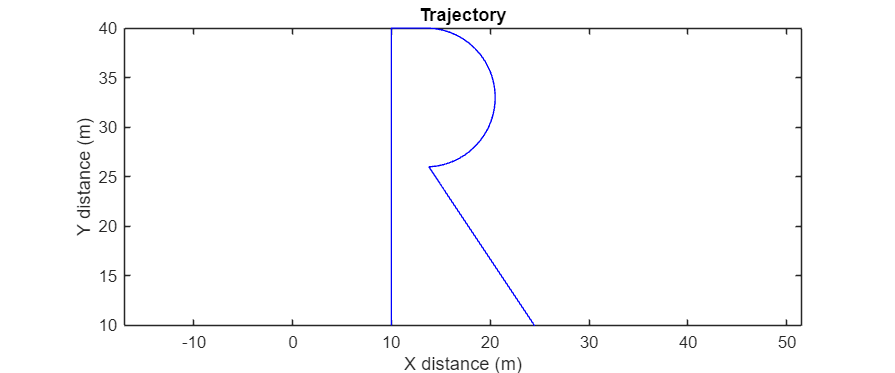


% ===== AUTHORS ===== %
% - Liam Murray
% - Sofia Simas
% - Lilly Mertzluft
% - Summer Chirpich
% - Satvik Kumar



% ===== INIT ========= %

clear
clc

%[targetTime, targetPosX, targetPosY] = obstaclePath();
[targetTime, targetPosX, targetPosY] = R_path();
astrobee = generateAstrobeeStruct();
dt = 0.0001;

% ===== SIMULATE ===== %

thrustProfiles = solveThrustProfiles(targetTime, targetPosX, targetPosY, astrobee, dt);
[time, posX, posY, velX, velY, theta, omega] = solvePath(astrobee, thrustProfiles);

% ===== DISPLAY ===== %
renderAnimation(time, targetTime, targetPosX, targetPosY, posX, posY, theta, thrustProfiles, astrobee);